%{
EX. 1. 

What is the order of the model if the input is f and the output is the speed of the mass?
|
In this case the system can be described by the formula:
m * vdot = f - dv 
Which can be rewritten as:
vdot + dv / m = f / m
The highest derivative of the output here is the first derivative and
therefore the model is of order 1.


If the output is the position of the mass, what is the order again?
|
In this case the system can be described by:
m * xddot = f - d * xdot
Which can be rewritten as:
xddot + (d * xdot) / m = f / m
The highest derivative of the output here is the second derivative and
therefore the model is of order 1. 
%}

m = 0.1; % kg
d = 0.5; % Ns/m

% Derived state space model:

A = [0, 1;
    0 -d/m];

B = [0; 1/m];

% u = F
% For position output 
C1 = [1, 0];
D = 0;

sys1 = ss(A, B, C1, D)

sys1 =
 
  A = 
       x1  x2
   x1   0   1
   x2   0  -5
 
  B = 
       u1
   x1   0
   x2  10
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


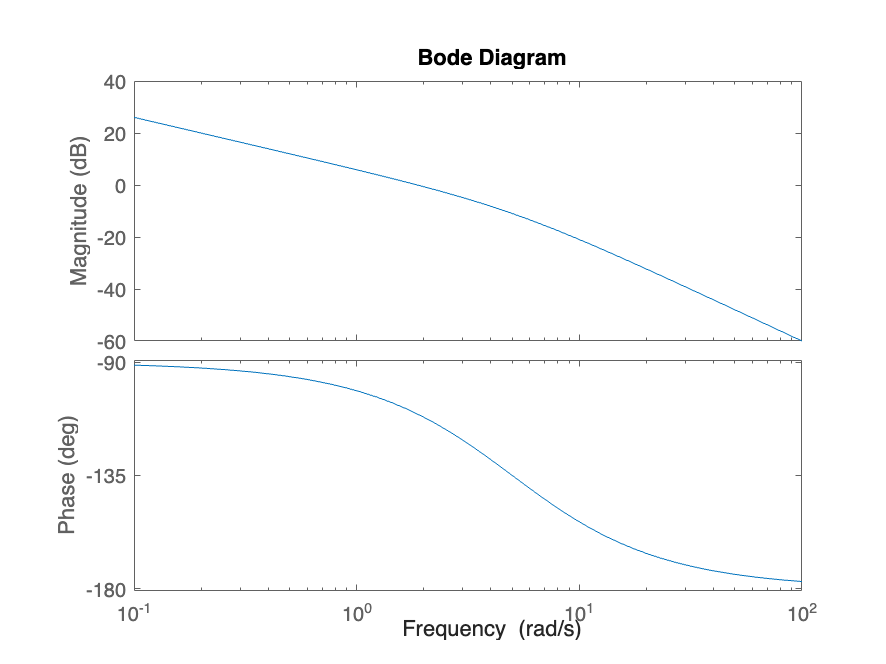

bode(sys1)


% For velocity output
C2 = [0, 1];
D = 0;

sys2 = ss(A, B, C2, D)

sys2 =
 
  A = 
       x1  x2
   x1   0   1
   x2   0  -5
 
  B = 
       u1
   x1   0
   x2  10
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


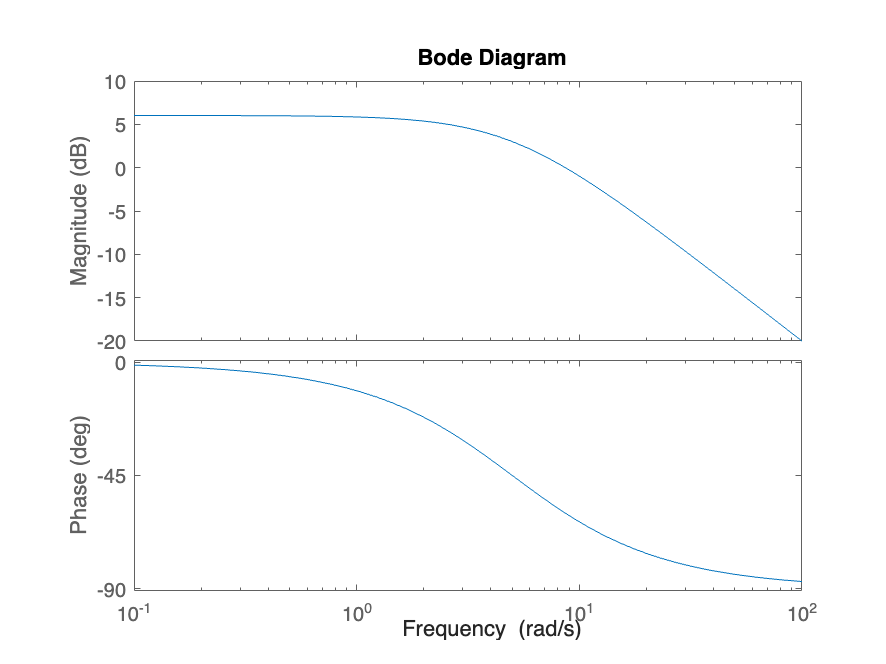

bode(sys2)


s = tf('s');

% Derived transfer function model for position output
G1 = 1 / (m*s^2 + d*s)

G1 =
 
         1
  ---------------
  0.1 s^2 + 0.5 s
 
Continuous-time transfer function.
Model Properties


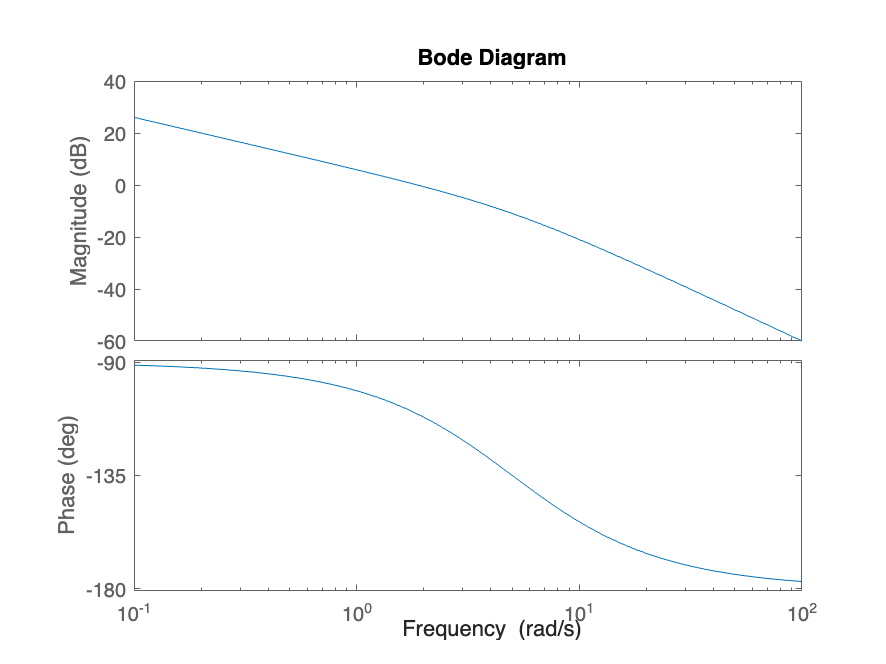

bode(G1);


% Derived transfer function model for velocity output
G2 = 1 / (m*s + d)

G2 =
 
       1
  -----------
  0.1 s + 0.5
 
Continuous-time transfer function.
Model Properties


bode(G2);

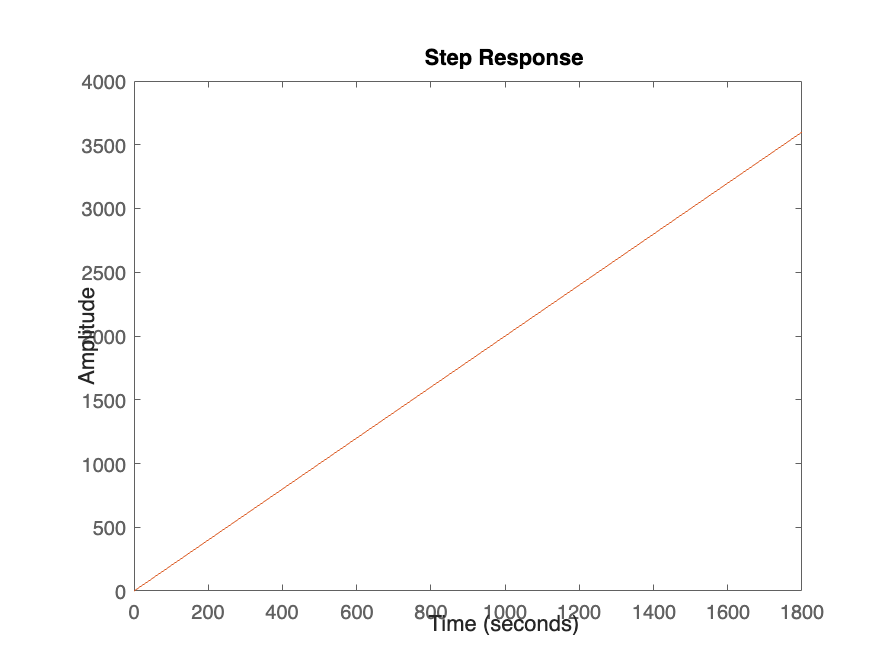


sp =

	resppack.timeplot




% Step response of system with position as output
sp = stepplot(sys1, G1)

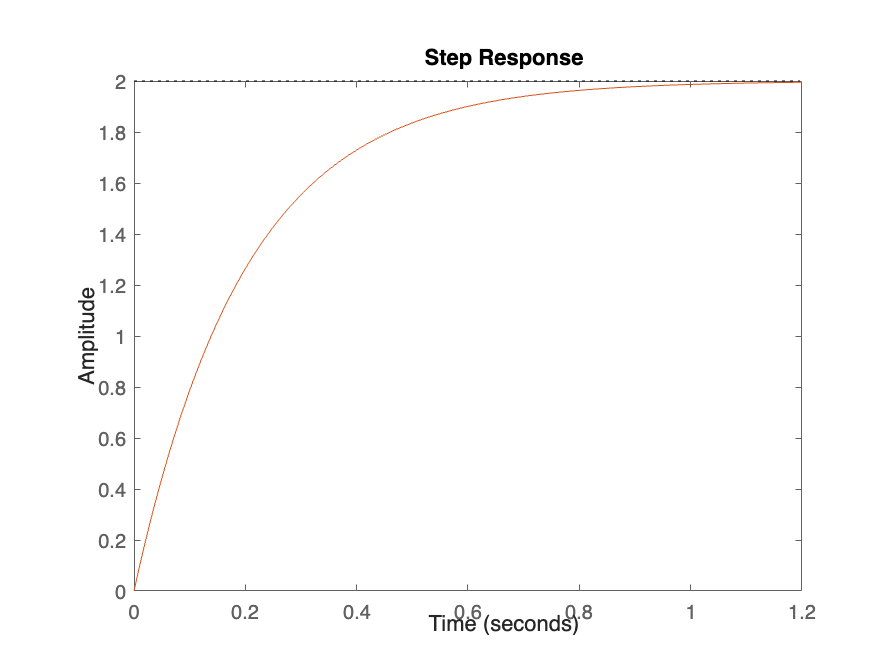


sp2 =

	resppack.timeplot




% Step response of a system with velocity as output
sp2 = stepplot(sys2, G2)

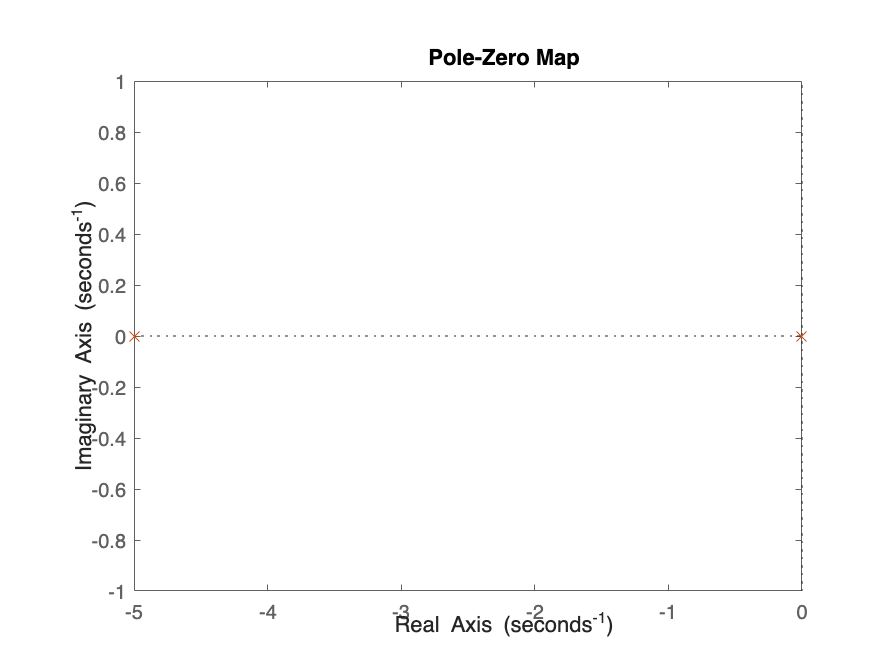


pzp =

	resppack.mpzplot




% Pole-zero plot of system with position as output
pzp = pzplot(sys1, G1)

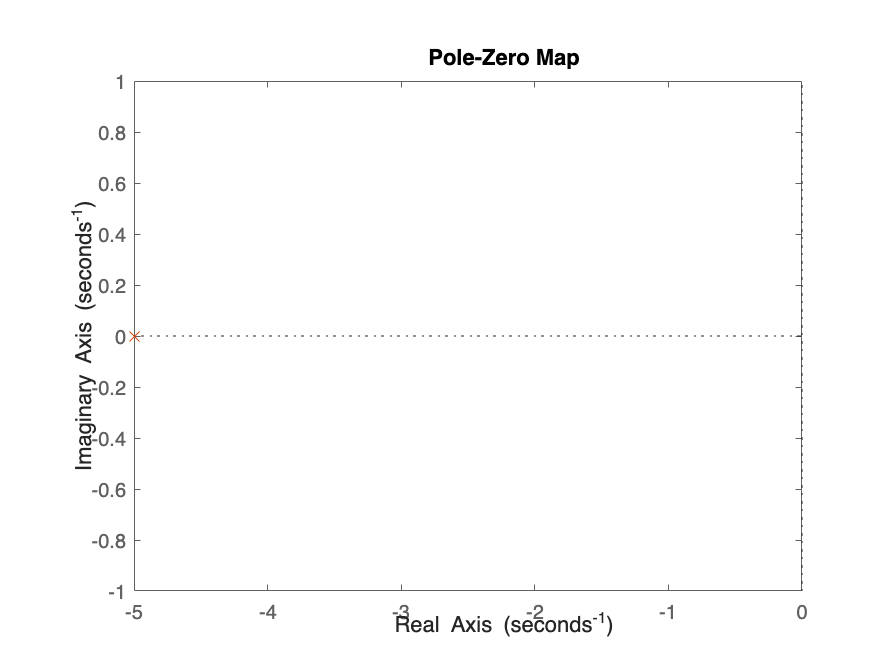


pzp =

	resppack.mpzplot




% Pole-zero plot of a system with velocity as output
pzp = pzplot(sys2, G2)